%%DESIGN OF SERVO SYSTEMS
%%Design of Type 1 Servo System when the Plant Has An Integrator.
num = 0.755;
den = [1, 13.87, 34.91];
A = [0        1;
     -34.91  -13.87];

B = [0  ; 0.755];

C = [1 0];

D = [0]

D = 0



Q = [ 20000 0;
      0  200];

R = [1];

% ***** If we enter the command [K,P,E] = lqr(A,B,Q,R), then *****
[K,P,E] = lqr(A,B,Q,R)

K =   102.5500   10.0746


P = 1.0e+03 *

    3.3829    0.1358
    0.1358    0.0133


E =    -9.0140
  -12.4624


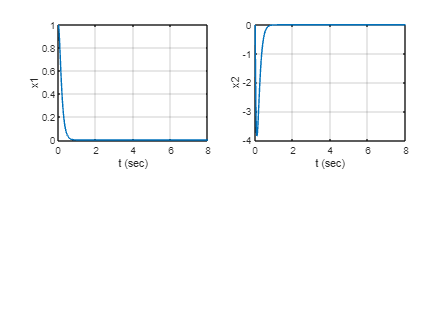

sys = ss(A-B*K, eye(2), eye(2), eye(2));
t = 0:0.01:8;
x = initial(sys,[1;0],t);
x1 = [1 0]*x';
x2 = [0 1]*x';
subplot(2,2,1); plot(t,x1); grid
xlabel('t (sec)'); ylabel('x1')
subplot(2,2,2); plot(t,x2); grid
xlabel('t (sec)'); ylabel('x2')